resolution = 1200;
fs = 8000;
duration = 0.1;
gap = 0.1;

[t_total,z] = generate_wave({"1","5","9","D"},fs,duration,gap);

### Low Pass 1 to 4 kHz

signal_low_1 = low_pass1(z,fs);
downsampled_signal_low_1 = downsample(signal_low_1, 2);

### Low Pass 2 to 2 kHz

signal_low_2 = low_pass2(downsampled_signal_low_1,fs/2);
downsampled_signal_low_2 = downsample(signal_low_2,2);

low_2_spectrum = fft(signal_low_2);
low_2_downsample_spectrum = fft(downsampled_signal_low_2);

figure()
subplot(2,1,1)
f_output = linspace(-fs/4, fs/4, length(low_2_spectrum));
plot(f_output, log(abs(fftshift(low_2_spectrum))));
grid on
title('Spectrum of Signal after 2nd Low-Pass Before 2nd Downsample');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

subplot(2,1,2)
f_output = linspace(-fs/8, fs/8, length(low_2_downsample_spectrum));
plot(f_output, log(abs(fftshift(low_2_downsample_spectrum))));
grid on
title('Spectrum of Signal after 2nd Low-Pass and Downsample');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

% exportgraphics(gcf, 'TeX/images/4D_LowSpectrumComparison.png', 'Resolution',resolution);

### High Pass 2 to 2 kHz

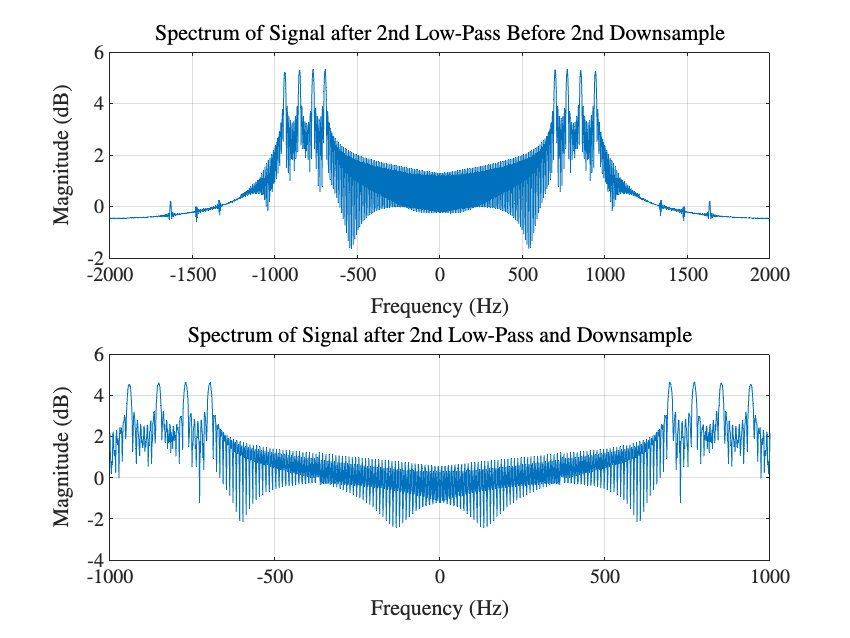

signal_high_2 = high_pass1(downsampled_signal_low_1,fs);

downsampled_signal_high_2 = downsample(signal_high_2,2)

downsampled_signal_high_2 =          0    0.0021    0.1980   -0.1800   -0.4615    0.6469   -0.3299   -0.1664    0.6486   -0.8611    0.6938   -0.2145   -0.3793    0.8355   -0.9586    0.6913   -0.1389   -0.4733    0.8932   -0.9463    0.6092   -0.0202   -0.5767    0.9333   -0.9009    0.4931    0.1198   -0.6818    0.9587   -0.8359    0.3655    0.2559   -0.7698    0.9635   -0.7573    0.2373    0.3811   -0.8416    0.9534   -0.6694    0.1066    0.5015   -0.9021    0.9275   -0.5663   -0.0315    0.6165   -0.9444    0.8784   -0.4465


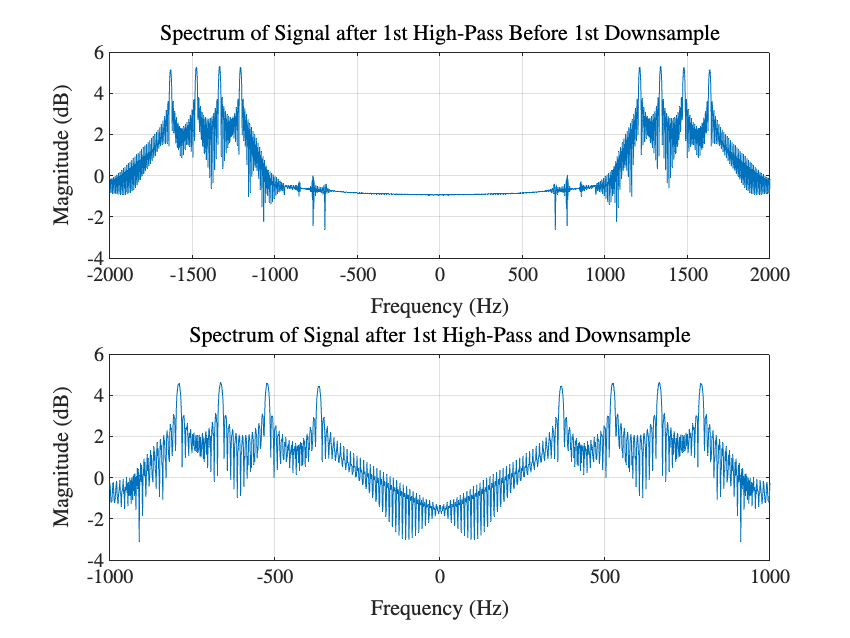


high_2_spectrum = fft(signal_high_2);
high_2_downsample_spectrum = fft(downsampled_signal_high_2);

figure()
subplot(2,1,1)
f_output = linspace(-fs/4, fs/4, length(high_2_spectrum));
plot(f_output, log(abs(fftshift(high_2_spectrum))));
grid on
title('Spectrum of Signal after 1st High-Pass Before 1st Downsample');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

subplot(2,1,2)
f_output = linspace(-fs/8, fs/8, length(high_2_downsample_spectrum));
plot(f_output, log(abs(fftshift(high_2_downsample_spectrum))));
grid on
title('Spectrum of Signal after 1st High-Pass and Downsample');
xlabel('Frequency (Hz)');
ylabel('Magnitude (dB)');

% exportgraphics(gcf, 'TeX/images/4D_HighSpectrumComparison.png', 'Resolution',resolution);